%% Step3_final.m - パターン一致度計算（外れ値分析付き）
% 修正点：
% 1. 同一カテゴリペア同士を比較するよう実装
% 2. 外れ値分析（IQR法）を追加
% 3. 全店舗 vs 外れ値除去後の両方を報告

%% 1. データ読み込み
if ~exist('rawData_dailySales', 'var')
    error('rawData_dailySales が見つかりません。rawData.matを先に読み込んでください。');
end

try
    load('step1_results.mat', 'analysisData');
    fprintf('✓ Step 1の結果を読み込みました\n');
catch
    error('step1_results.mat が見つかりません。');
end

✓ Step 1の結果を読み込みました



%% 2. TOP10カテゴリの取得
if isfield(analysisData, 'top10Categories')
    uniqueCategories = analysisData.top10Categories;
    globalSalesMatrix = analysisData.top10SalesMatrix;
    fprintf('✓ TOP10カテゴリを使用します\n');
else
    uniqueCategories = analysisData.categoryStats.MajorCategory(1:10);
    top10Idx = false(size(analysisData.salesMatrix, 1), 1);
    for i = 1:length(uniqueCategories)
        top10Idx = top10Idx | (analysisData.uniqueCategories == uniqueCategories(i));
    end
    globalSalesMatrix = analysisData.salesMatrix(top10Idx, :);
    fprintf('✓ categoryStatsからTOP10カテゴリを取得しました\n');
end

✓ TOP10カテゴリを使用します



nCategories = length(uniqueCategories);
nDates = size(globalSalesMatrix, 2);
fprintf('カテゴリ数: %d, 日数: %d\n', nCategories, nDates);

カテゴリ数: 10, 日数: 366



%% 3. 基準パターン（相関行列）
globalCorrMatrix = corrcoef(globalSalesMatrix');
fprintf('✓ 基準パターン（相関行列）を計算しました\n');

✓ 基準パターン（相関行列）を計算しました



%% 4. 店舗リストの取得
storeList = unique(rawData_dailySales.BookstoreCode);
nStores = length(storeList);
fprintf('店舗数: %d店舗\n', nStores);

店舗数: 35店舗



%% 5. 店舗別データ集計
fprintf('店舗別データを集計中...\n');

店舗別データを集計中...


storeDailyCategorySales = grpstats(rawData_dailySales, ...
    {'BookstoreCode', 'Date', 'MajorCategory'}, ...
    'sum', 'DataVars', 'POSSalesVolume');
fprintf('集計完了: %d レコード\n', height(storeDailyCategorySales));

集計完了: 263409 レコード



%% 6. 店舗別相関行列の計算
storeCorrMatrices = nan(nCategories, nCategories, nStores);
storeValidFlags = false(nStores, 1);
storeTotalSales = zeros(nStores, 1);
minValidDays = 30;

uniqueDates = analysisData.uniqueDates;

for s = 1:nStores
    storeCode = storeList(s);
    storeData = storeDailyCategorySales(storeDailyCategorySales.BookstoreCode == storeCode, :);
    
    if isempty(storeData)
        continue;
    end
    
    storeTotalSales(s) = sum(storeData.sum_POSSalesVolume);
    storeSalesMatrix = zeros(nCategories, nDates);
    
    for i = 1:height(storeData)
        catIdx = find(uniqueCategories == storeData.MajorCategory(i));
        if ~isempty(catIdx)
            dateIdx = find(uniqueDates == storeData.Date(i));
            if ~isempty(dateIdx)
                storeSalesMatrix(catIdx, dateIdx) = storeData.sum_POSSalesVolume(i);
            end
        end
    end
    
    validDays = sum(storeSalesMatrix > 0, 1) >= ceil(nCategories / 2);
    nValidDays = sum(validDays);
    
    if nValidDays >= minValidDays
        validData = storeSalesMatrix(:, validDays);
        validCats = std(validData, 0, 2) > 0;
        
        if sum(validCats) >= ceil(nCategories / 2)
            fullCorrMat = nan(nCategories, nCategories);
            validCorrMat = corrcoef(validData(validCats, :)');
            validIdx = find(validCats);
            for ii = 1:length(validIdx)
                for jj = 1:length(validIdx)
                    fullCorrMat(validIdx(ii), validIdx(jj)) = validCorrMat(ii, jj);
                end
            end
            storeCorrMatrices(:, :, s) = fullCorrMat;
            storeValidFlags(s) = true;
        end
    end
end

nValidStores = sum(storeValidFlags);
fprintf('有効店舗数: %d / %d\n', nValidStores, nStores);

有効店舗数: 35 / 35



%% 7. パターン一致度の計算
patternSimilarity = nan(nStores, 1);
upperTriIdx = triu(true(nCategories), 1);
globalVec = globalCorrMatrix(upperTriIdx);

for s = 1:nStores
    if ~storeValidFlags(s)
        continue;
    end
    
    storeCorrMat = storeCorrMatrices(:, :, s);
    storeVec = storeCorrMat(upperTriIdx);
    validPairs = ~isnan(globalVec) & ~isnan(storeVec);
    
    if sum(validPairs) >= 10
        r = corrcoef(globalVec(validPairs), storeVec(validPairs));
        patternSimilarity(s) = r(1, 2);
    end
end

%% 8. 全店舗での相関分析
validStoreIdx = find(~isnan(patternSimilarity));
nValidForCorr = length(validStoreIdx);

validSimilarity = patternSimilarity(validStoreIdx);
validSales = storeTotalSales(validStoreIdx);

[r_all, p_all] = corrcoef(validSimilarity, validSales);
fprintf('\n=== パターン一致度 vs 総販売冊数（全店舗）===\n');


=== パターン一致度 vs 総販売冊数（全店舗）===


fprintf('  相関係数 r = %.3f\n', r_all(1,2));

  相関係数 r = 0.517


fprintf('  p値 = %.4f\n', p_all(1,2));

  p値 = 0.0015


fprintf('  有効店舗数 n = %d\n', nValidForCorr);

  有効店舗数 n = 35



%% 9. 外れ値分析（IQR法）
Q1 = prctile(validSimilarity, 25);
Q3 = prctile(validSimilarity, 75);
IQR_val = Q3 - Q1;
lowerBound = Q1 - 1.5 * IQR_val;
upperBound = Q3 + 1.5 * IQR_val;

fprintf('\n=== 外れ値判定（IQR法）===\n');


=== 外れ値判定（IQR法）===


fprintf('Q1 = %.3f, Q3 = %.3f, IQR = %.3f\n', Q1, Q3, IQR_val);

Q1 = 0.621, Q3 = 0.830, IQR = 0.208


fprintf('下限 = %.3f, 上限 = %.3f\n', lowerBound, upperBound);

下限 = 0.309, 上限 = 1.142



% 外れ値フラグ
outlierFlags = (patternSimilarity < lowerBound | patternSimilarity > upperBound) & ~isnan(patternSimilarity);
outlierIdx = find(outlierFlags);
nOutliers = length(outlierIdx);

fprintf('\n外れ値の数: %d\n', nOutliers);


外れ値の数: 2


if nOutliers > 0
    fprintf('外れ値の店舗:\n');
    for i = 1:nOutliers
        fprintf('  店舗%d: 一致度 = %.3f, 総販売冊数 = %.0f\n', ...
            storeList(outlierIdx(i)), patternSimilarity(outlierIdx(i)), storeTotalSales(outlierIdx(i)));
    end
end

外れ値の店舗:


  店舗26: 一致度 = 0.223, 総販売冊数 = 8438
  店舗27: 一致度 = 0.034, 総販売冊数 = 12155



%% 10. 外れ値除去後の相関分析
noOutlierIdx = find(~isnan(patternSimilarity) & ~outlierFlags);
nNoOutlier = length(noOutlierIdx);

[r_noOutlier, p_noOutlier] = corrcoef(patternSimilarity(noOutlierIdx), storeTotalSales(noOutlierIdx));

fprintf('\n=== パターン一致度 vs 総販売冊数（外れ値除去後）===\n');


=== パターン一致度 vs 総販売冊数（外れ値除去後）===


fprintf('  相関係数 r = %.3f（除去前: %.3f）\n', r_noOutlier(1,2), r_all(1,2));

  相関係数 r = 0.322（除去前: 0.517）


fprintf('  p値 = %.4f\n', p_noOutlier(1,2));

  p値 = 0.0674


fprintf('  有効店舗数 n = %d（除去前: %d）\n', nNoOutlier, nValidForCorr);

  有効店舗数 n = 33（除去前: 35）


fprintf('  変化率: %.1f%%\n', (r_noOutlier(1,2) - r_all(1,2)) / r_all(1,2) * 100);

  変化率: -37.7%



%% 11. 典型店舗・異質店舗
[maxSim, maxIdx] = max(patternSimilarity);
[minSim, minIdx] = min(patternSimilarity);

fprintf('\n=== 典型店舗・異質店舗 ===\n');


=== 典型店舗・異質店舗 ===


fprintf('典型店舗: 店舗%d（一致度: %.3f）\n', storeList(maxIdx), maxSim);

典型店舗: 店舗23（一致度: 0.922）


fprintf('異質店舗: 店舗%d（一致度: %.3f）%s\n', storeList(minIdx), minSim, ...
    iif(outlierFlags(minIdx), ' ※外れ値', ''));

異質店舗: 店舗27（一致度: 0.034） ※外れ値


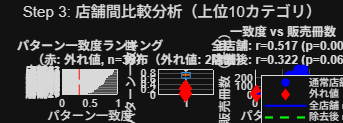


%% 12. 可視化
figure('Position', [100, 100, 1400, 500]);
sgtitle('Step 3: 店舗間比較分析（上位10カテゴリ）');

% (a) パターン一致度のランキング
subplot(1, 3, 1);
[sortedSim, sortIdx] = sort(patternSimilarity, 'descend');
validSortIdx = sortIdx(~isnan(sortedSim));
validSortedSim = sortedSim(~isnan(sortedSim));

barColors = repmat([0.3 0.6 0.9], length(validSortIdx), 1);
for i = 1:length(validSortIdx)
    if outlierFlags(validSortIdx(i))
        barColors(i, :) = [0.9 0.3 0.3];  % 外れ値は赤
    end
end

for i = 1:length(validSortIdx)
    barh(i, validSortedSim(i), 'FaceColor', barColors(i,:));
    hold on;
end
hold off;
yticks(1:length(validSortIdx));
yticklabels(arrayfun(@(x) sprintf('店舗%d', storeList(x)), validSortIdx, 'UniformOutput', false));
xlabel('パターン一致度');
title(sprintf('パターン一致度ランキング\n（赤: 外れ値, n=%d）', nValidForCorr));
set(gca, 'YDir', 'reverse');
xline(lowerBound, 'r--', 'LineWidth', 1);
grid on;

% (b) 箱ひげ図
subplot(1, 3, 2);
boxplot(validSimilarity);
hold on;
scatter(ones(nOutliers, 1), patternSimilarity(outlierIdx), 80, 'r', 'filled', 'd');
hold off;
ylabel('パターン一致度');
title(sprintf('分布（外れ値: %d店舗）', nOutliers));
grid on;

% (c) 一致度 vs 総販売冊数（外れ値ハイライト）
subplot(1, 3, 3);
normalIdx = find(~outlierFlags & ~isnan(patternSimilarity));
scatter(patternSimilarity(normalIdx), storeTotalSales(normalIdx)/1000, 50, 'b', 'filled');
hold on;
if nOutliers > 0
    scatter(patternSimilarity(outlierIdx), storeTotalSales(outlierIdx)/1000, 80, 'r', 'filled', 'd');
end
% 回帰直線（全データ）
p_fit_all = polyfit(validSimilarity, validSales/1000, 1);
x_line = linspace(min(validSimilarity), max(validSimilarity), 100);
plot(x_line, polyval(p_fit_all, x_line), 'b-', 'LineWidth', 1.5);
% 回帰直線（外れ値除去後）
p_fit_no = polyfit(patternSimilarity(noOutlierIdx), storeTotalSales(noOutlierIdx)/1000, 1);
x_line2 = linspace(min(patternSimilarity(noOutlierIdx)), max(patternSimilarity(noOutlierIdx)), 100);
plot(x_line2, polyval(p_fit_no, x_line2), 'g--', 'LineWidth', 1.5);
hold off;
xlabel('パターン一致度');
ylabel('総販売冊数（千冊）');
legend({'通常店舗', '外れ値', sprintf('全店舗 r=%.3f', r_all(1,2)), sprintf('除去後 r=%.3f', r_noOutlier(1,2))}, ...
    'Location', 'northwest');
title(sprintf('一致度 vs 販売冊数\n全店舗: r=%.3f (p=%.3f)\n除去後: r=%.3f (p=%.3f)', ...
    r_all(1,2), p_all(1,2), r_noOutlier(1,2), p_noOutlier(1,2)));
grid on;

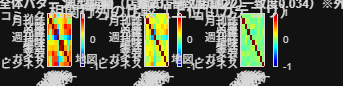


%% 13. 相関行列比較の可視化
figure('Position', [100, 100, 1400, 350]);
sgtitle('相関行列の比較（上位10カテゴリ）');

catLabels = cellstr(uniqueCategories);
for i = 1:length(catLabels)
    if length(catLabels{i}) > 6
        catLabels{i} = catLabels{i}(1:6);
    end
end

subplot(1, 3, 1);
imagesc(globalCorrMatrix);
colormap('jet'); colorbar; caxis([-1, 1]);
title('全体パターン（基準）');
xticks(1:nCategories); yticks(1:nCategories);
xticklabels(catLabels); yticklabels(catLabels);
xtickangle(45);

subplot(1, 3, 2);
imagesc(storeCorrMatrices(:, :, maxIdx));
colormap('jet'); colorbar; caxis([-1, 1]);
title(sprintf('典型店舗（店舗%d, 一致度%.3f）', storeList(maxIdx), maxSim));
xticks(1:nCategories); yticks(1:nCategories);
xticklabels(catLabels); yticklabels(catLabels);
xtickangle(45);

subplot(1, 3, 3);
imagesc(storeCorrMatrices(:, :, minIdx));
colormap('jet'); colorbar; caxis([-1, 1]);
title(sprintf('異質店舗（店舗%d, 一致度%.3f）※外れ値', storeList(minIdx), minSim));
xticks(1:nCategories); yticks(1:nCategories);
xticklabels(catLabels); yticklabels(catLabels);
xtickangle(45);


%% 14. 結果の保存
step3Results = struct();
step3Results.globalCorrMatrix = globalCorrMatrix;
step3Results.storeCorrMatrices = storeCorrMatrices;
step3Results.patternSimilarity = patternSimilarity;
step3Results.storeValidFlags = storeValidFlags;
step3Results.storeTotalSales = storeTotalSales;
step3Results.storeList = storeList;

% 全店舗の結果
step3Results.all.nValid = nValidForCorr;
step3Results.all.r = r_all(1,2);
step3Results.all.p = p_all(1,2);
% 
% 外れ値情報
step3Results.outlier.flags = outlierFlags;
step3Results.outlier.idx = outlierIdx;
step3Results.outlier.nOutliers = nOutliers;
step3Results.outlier.lowerBound = lowerBound;
step3Results.outlier.upperBound = upperBound;

% 外れ値除去後の結果
step3Results.noOutlier.idx = noOutlierIdx;
step3Results.noOutlier.nValid = nNoOutlier;
step3Results.noOutlier.r = r_noOutlier(1,2);
step3Results.noOutlier.p = p_noOutlier(1,2);

% 典型・異質店舗
step3Results.typicalStore = struct('idx', maxIdx, 'code', storeList(maxIdx), 'similarity', maxSim);
step3Results.atypicalStore = struct('idx', minIdx, 'code', storeList(minIdx), 'similarity', minSim, ...
    'isOutlier', outlierFlags(minIdx));

save('step3_results.mat', 'step3Results');
fprintf('\n✓ 結果を step3_results.mat に保存しました\n');


✓ 結果を step3_results.mat に保存しました



%% ヘルパー関数
function result = iif(condition, trueVal, falseVal)
    if condition
        result = trueVal;
    else
        result = falseVal;
    end
end